# Board Calculator

## Description

This script has been written in order to determine the number of boards that will be required to cover a particular shape. In my case, I have designed a desk that looks like this:

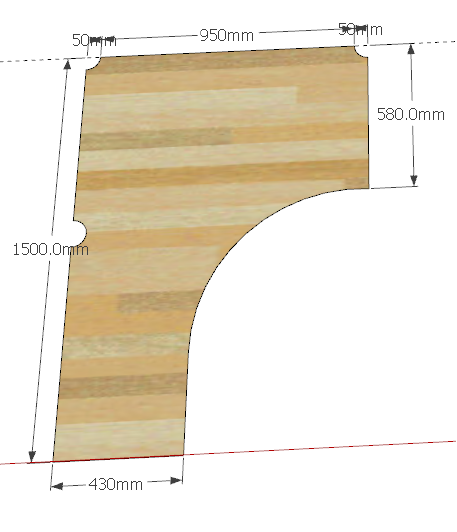

This script needs to work out what amount of material would be needed to build this.

Written by: Christopher Armstrong

## Change Log

For prescriptive documentation of changes, refer to the change history within the revision control system.

Version 0.2 - 10/12/2020

- Converted from a Live Script into a Live Function in order to be able to run optimisations

Version 0.1 - 19th August 2020

- Initial generation of script

Brief summary of this function.

Detailed explanation of this function.

function totalBoardLength = boardLengthCalculator(boardWidth)


## Define the area to be covered

A MATLAB array will be used to create a binary map that represents the desk area which is required to be covered.

A resolution of one element = 10 mm has been chosen.

yDimension = 1500; % mm
xDimension = 1050; % mm
deskAreaMap = false(yDimension / 10 ,xDimension / 10);

Now we set the perimeter values of the desk to true.

deskAreaMap(:,1) = true;        % left hand edge
deskAreaMap(1,:) = true;        % top edge
deskAreaMap(end, 1:43) = true;  % bottom edge
deskAreaMap(1:58, end) = true;  % right hand straight edge

And the curved section will be represented as a straight line for simplicity

% Calculate the gradient of line
x1 = 43;
x2 = 105;

y1 = 150;
y2 = 58;

% Because MATLAB uses y = 0 at the top, rather than the bottom, y1 & y2 are
% reversed
m = (y2 - y1) / (x2 - x1);
%m = (x1 - x2) / (y1 - y2)
disp(m);


% Calculate the y-axis intercept using x1 & y1
% normally y = mx + c
% rearrange to make c the subjet
% c = y - mx
% substiute in:
%   y = y1
%   m = m
%   x = x1

c = y1 - m * x1;
disp(c);

Now that we have values of the m and c co-effecients in the y=mx + c equation. We can calculate the co-ordinates of what pixels should be used to represent the curved edge.

If we state that we want every column (i.e. x-values) to be populated then we can define the range of column indicies to be:

cols = 43:105;


We can then use the equation to determine the row numbers (y-coordinates)

rows = m * cols + c;
rows = floor(rows);
disp(rows);

Knowing the rows and columns, we can now set those values to be true

coords = [rows; cols]';
disp(coords);

for idx = 1:length(coords)
    currentCoordinate = coords(idx, :);
    deskAreaMap(currentCoordinate(1), currentCoordinate(2)) = true;
end


Visualise the result

imagesc(deskAreaMap)

## Start determining board lengths required for each row

First of all we can very easily determine the number of rows of boards required because this is simply the height divided by the board width.

%boardWidth = 220;    % mm
nBoards = yDimension / boardWidth;
nBoards = ceil(nBoards);
disp(nBoards);

Create a board map

boardMap = zeros(size(deskAreaMap));

for boardIdx = nBoards : -1 : 1
    startingDimension = ((boardIdx - 1) * boardWidth) / 10 + 1;
    startingDimension = floor(startingDimension);
    endDimension = startingDimension + boardWidth / 10;
    boardMap(startingDimension:endDimension, :)= boardIdx;
    
    

Now we want to work out the length that each board will need to be to span the full width that it is expected to cover. First of all let us extract the rows from the boardMap that relate to the area that this board will cover.

    if endDimension > yDimension / 10
        % CASE: The lower edge of the board wil "hang off" the bottom
        % ACTION: Cap "endDimension" to yDimension / 10 for now
        endDimension = yDimension / 10;
    end
    thisBoardMap = deskAreaMap(startingDimension:endDimension, :);
    
    %imagesc(thisBoardMap)
    
    

Next we need to identify the column that represents the right-most true value. There will always be at least two values, the first value will represent the left-hand edge, the second, or more precisely the largest value represents the coordinate of the right most edge.

    % First row
    pks = find(thisBoardMap(1,:) == true);
    firstEdge = max(pks);
    
    % Second row
    pks = find(thisBoardMap(2,:) == true);
    
    if length(pks) == 1
        % CASE: right-hand value was now present
        % ACTION: use the above row value
        secondEdge = firstEdge;
    end
    secondEdge = max(pks);
    
    % Third row
    pks = find(thisBoardMap(3,:) == true);
    thirdEdge = max(pks);
    

Now we have co-ordinates for the right-hand edge across the width of the board. We will take the maximum of these, plus we will add an excess to the required board length to give some "wiggle room".

    excess = 1;
    reqdBoardLength(boardIdx) = max([firstEdge secondEdge thirdEdge]) + excess * 10;
end

## Final Calculation

We have worked out the length of each board (with some excess) that would cover each "row" of the desk. Now we want the total board length required.

totalBoardLength = sum(reqdBoardLength);
disp(totalBoardLength);

imagesc(boardMap)

end